# 高频-低频参数辨识

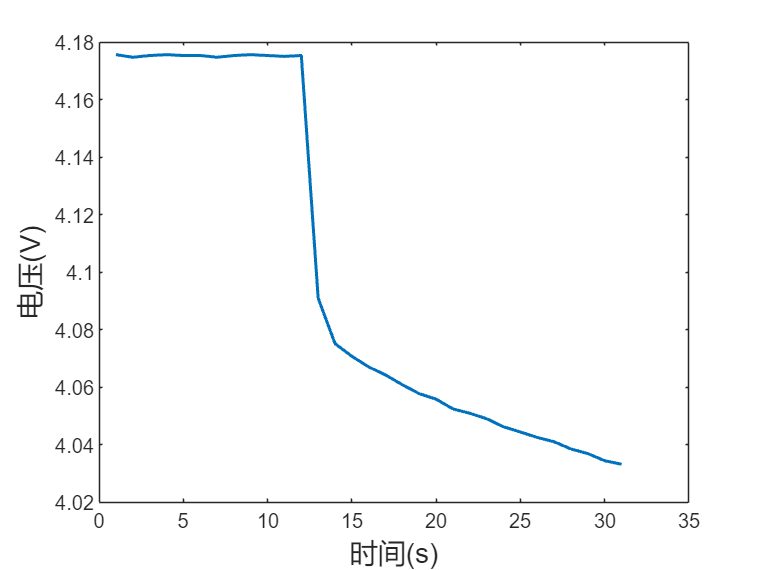

% clear;
% clc;

load nmc_cccd.mat;

I=nmc_cccd.Cur/1000;
V=nmc_cccd.Vol;
Q=nmc_cccd.Q;
t=nmc_cccd.t;


figure(1);
clf;
plot(V(3590:3590+30),LineWidth=1.5);
xlabel('时间(s)','fontsize',14);
ylabel('电压(V)','fontsize',14);

R_ohm=(V(3601)-V(3602))/2.5

R_ohm =       0.03372


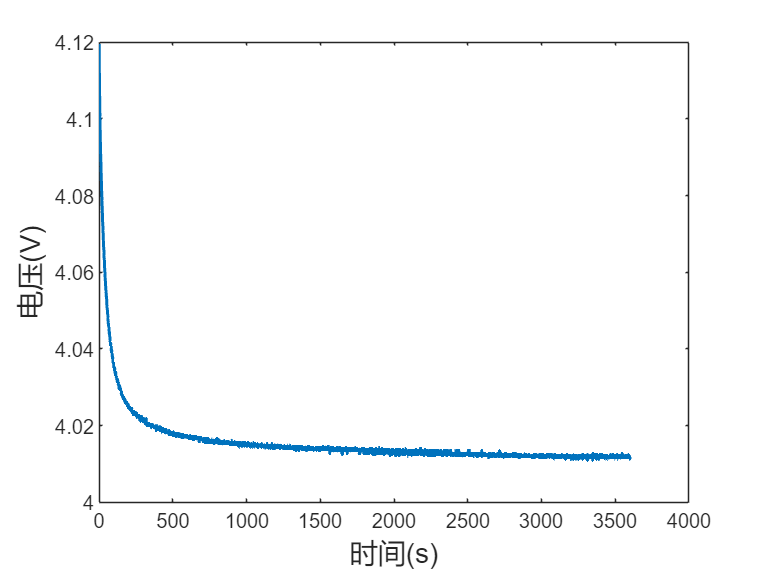

figure(2);
clf;
plot(V(8105:end),LineWidth=1.5); %8105
xlabel('时间(s)','fontsize',14);
ylabel('电压(V)','fontsize',14);

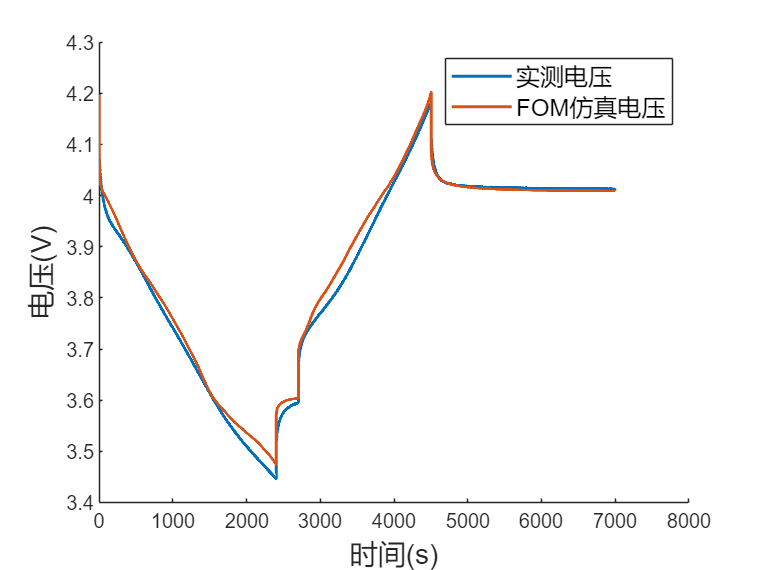

% setting = optimoptions('particleswarm','SwarmSize',500,'Display','iter','MaxIterations',500);
% [x1,evalu] = particleswarm(@findtau,2,[1000,1000],[10000,10000],setting)
% x1=[4612.98543361585	5000];
x1=[4342.68784525913	7489.98335011751];
I=I(3601:3601+7000);
V=V(3601:3601+7000);
Q=Q(3601:3601+7000);
t=t(3601:3601+7000);

% x=[0.278341730585941,3.61137408174925,0.987069383657047,2.70544455127934];
x=[0.2615,3.61137408174925,0.9966,2.70544455127934];
thetap0=x(1);
Qp=x(2);
thetan0=x(3);
Qn=x(4);

taup=x1(1);
taun=x1(2);

dthetap_surf=fom(taup,I)/3600/Qp/3;
thetap=thetap0-cumsum(I/3600/Qp);
thetap_surf=thetap-dthetap_surf;

dthetan_surf=fom(taun,I)/3600/Qn/3;
thetan=thetan0+cumsum(I/3600/Qn);
thetan_surf=thetan+dthetan_surf;

V_fom=Eeq_NMC(thetap_surf)-Eeq_MCMB(thetan_surf)+I*R_ohm;

figure(3);
clf;
hold on;
plot(V,LineWidth=1.5);
plot(V_fom,LineWidth=1.5);
legend('实测电压','FOM仿真电压',fontsize=12);
xlabel('时间(s)','fontsize',14);
ylabel('电压(V)','fontsize',14);

RMSE(V_fom,V)*1000

ans =         18.05


MAPE(V_fom,V)

ans =       0.36225


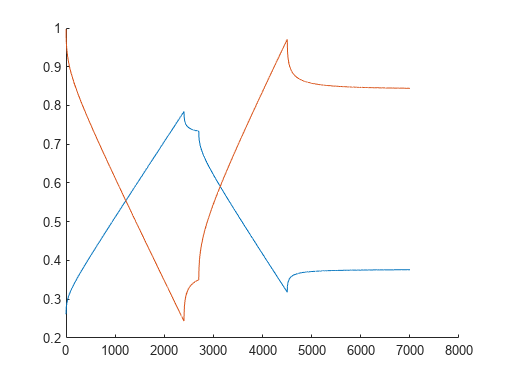

figure(4);
clf;
hold on;
plot(thetap_surf);
plot(thetan_surf);